# ** Análisis de supervivencia para cáncer de páncreas con datos transcriptómicos (TCGA-PDAC). **

# **Parte 2 - Análisis de supervivencia por gen, log-rank test y cox uni y multivariado. **

### **Descripción general del código. **

El script PAAD_supervivencia_KM_Cox analiza si la expresión de los genes de interés se asocia con la supervivencia global de los pacientes con PDAC de TCGA-PAAD. Parte de la cohorte final construida en el script de control de calidad (100 pacientes, 56 eventos).

Para cada gen hace dos análisis complementarios. Primero divide a los pacientes en expresión alta y baja según la mediana, y compara su supervivencia con curvas de Kaplan–Meier y la prueba log-rank. Después analiza la expresión como variable continua con regresión de Cox, sola y ajustada por edad, estadio y pureza tumoral, y verifica el supuesto de riesgos proporcionales. Los resultados se corrigen por comparaciones múltiples y se resumen en un forest plot.

Su importancia es que, a diferencia de comparar vivos contra fallecidos, considera el tiempo de seguimiento de cada paciente. Además, el modelo de Cox continuo tiene más poder estadístico, y el ajuste por covariables permite distinguir si el efecto de un gen es independiente de otros factores pronósticos. Así se identifica qué genes tienen valor pronóstico, lo que orienta la búsqueda de biomarcadores y el siguiente paso del proyecto: integrar los datos de proteína y fosforilación (RPPA).

**Código. **

### **Sección 0. Limpieza de Command Window y Workspace. **

clear; clc; close all;

### Sección 1. Rutas y parámetros. 

Esta primera sección del código define la ubicación de los archivos, dónde se guardaran los resultados y algunos parámetros de las figuras que se generarán en el transcurso del código. Antes de correr el script, se deben ajustar las direcciones de las rutas correspondientes.

Primero se define la carpeta principal del proyecto (rutaBase), y a partir de ellas se construyen las demás rutas con la función "fullfile", que une las carpetas con el separador correcto de Windows, "carpetaSal" es la carpeta "Resultados_Supervivencia", la misma donde el script de cohorte y el control de calidad guardó sus resultados. Este script la usa para leer y para escribir: de ahí toma la cohorte y ahí guarda las tablas de resultados, el panel de curvas y el forest plot. "rutaCoh" apunta al archivo "Cohorte_supervivencia_OS.csv", la cohorte final con una fila por paciente, su tiempo, su evento, sus covariables y la expresión de los genes. Por eso el script de cohorte y control de calidad debe correrse antes: si ese archivo no existe, este script no puede empezar.

"carpetaFig" es la subcarpeta "Figuras_M", donde se guarda una figura de Kaplan-Meier por gen. 

Después se definen dos parámetros visuales. "colores" es una matriz con dos colores en formato RGB, con valores de 0 a 1: la primera fila es el azul del grupo de expresión baja y la segunda el narajnja del grupo de "expresión alta". Se fijan para que todas las curvas usen la misma convención de colores. "pasoMeses" = 12 define que las marcas del eje horizontal y las columnas de la tabla de pacientes en riesgo aparezcan cada 12 meses. 

Por último, el código verifica si existe la carpeta "Figuras_KM" y, si no existe, la crea con "mkdir". Asi las figuras individuales pueden guardarse sin errores la primera vez que se corre el script. 

rutaBase   = "C:\PAP Keyla Otoño 2026\Downloaded_Data_Cohort_Pancreas";
carpetaSal = fullfile(rutaBase, "Resultados_Supervivencia");
rutaCoh    = fullfile(carpetaSal, "Cohorte_supervivencia_OS.csv");
carpetaFig = fullfile(carpetaSal, "Figuras_KM");

colores = [0.00 0.45 0.74;    % Bajo
           0.85 0.33 0.10];   % Alto
pasoMeses = 12;               % marcas del eje X y de la tabla "en riesgo"

if ~isfolder(carpetaFig), mkdir(carpetaFig);
end

### Sección 2. Lectura de la cohorte y preparación de covariables. 

Esta sección lee la cohorte final y prepara las variables que usarán los análisis de supervivencia: el tiempo, el evento, los genes y las covariables del modelo de Cox ajustado. 

Primero lee el archivo "Cohorte_supervivencia_OS.csv" y lo guarda en la tabla "D", con una fila por paciente. Después, identifica los genes automáticamente: busca las columnas cuyo nombre empieza con "log2_", el prefijo que les puso el script de control de calidad, y les quita ese prefijo para obtener los nombres de los genes. Gracias a esto, el script funciona con cualquier panel sin modificar el código y, si hay un cambio se detecta solo. "nG" guarda cuántos genes hay. 

Luego guarda en dos variables cortas las columnas que definen la supervivencia "t", el tiempo en meses, y "e", el evento (1 si el paciente murió y 0 si está censurado). Imprime un resumen con el número de pacientes, de eventos y de censurados, y la lista de genes encontrados, 

Después prepara el estadio como covariable. En lugar de usar las categprías I, II, III, lo convierte en una variable binaria, "estadio_avanzado". Vale 1 para los estadios IIB y III, que implican ganglios positivos o mayor avance local, y 0 para los estadios I y IIA. En esta cohorte en especifico casi todos los pacientes están en estadio II y los estadios I y III tienen tan pocos pacientes que el modelo no podría estimar el efecto con precisión. Los pacientes sin estadio quedan con "NaN". El script imprime la tabla de estadios original y cuántos pacientes quedan en cada grupo binario. 

Por último, reescala la edad y la pureza para que sus hazard ratios sean fáciles de interpretar. La edad se divide entre 10, de modo que su HR indica el cambio en el riesgo por cada 10 años de edad en lugar de por cada año. La pureza se multiplica por 10, de modo que su HR indica el cambio en el riesgo por cada 0.1 de pureza, en lugar de por un cambio de 0 a 1, que no tiene sentido práctico. Estos cambios de escala no alteran los resultados del modelo; solo hacen que los números sean más fáciles de leer. 

D = readtable(rutaCoh, 'TextType','string', 'VariableNamingRule','preserve');
colsG = string(D.Properties.VariableNames(startsWith(D.Properties.VariableNames, "log2_")));
genes = extractAfter(colsG, "log2_");
nG    = numel(genes);

t = D.tiempo_meses;
e = D.evento;
fprintf("Cohorte: %d pacientes | eventos: %d | censurados: %d\n", height(D), sum(e), sum(e == 0));

Cohorte: 100 pacientes | eventos: 56 | censurados: 44


fprintf("Genes (%d): %s\n\n", nG, strjoin(genes, ", "));

Genes (9): PDGFRB, CREB1, RB1, RICTOR, MAPK7, STAT3, MTSS1, PTPN11, SRC




% Estadio binario: IIB–III (ganglios positivos o avance local) vs I–IIA.
% Se usa binario porque los estadios I y III tienen pocos pacientes en PDAC.
sinEstadio = ismissing(D.estadio) | D.estadio == "";
D.estadio_avanzado = double(startsWith(D.estadio, "Stage IIB") | startsWith(D.estadio, "Stage III"));
D.estadio_avanzado(sinEstadio) = NaN;
fprintf("Estadio patológico:\n");

Estadio patológico:


disp(groupcounts(D, "estadio"));

      estadio      GroupCount    Percent
    ___________    __________    _______

    "Stage IA"          3           3   
    "Stage IB"          6           6   
    "Stage IIA"        17          17   
    "Stage IIB"        70          70   
    "Stage III"         2           2   
    <missing>           2           2   



fprintf("Estadio binario -> I–IIA: %d | IIB–III: %d | sin dato: %d\n\n", ...
    sum(D.estadio_avanzado == 0), sum(D.estadio_avanzado == 1), sum(sinEstadio));

Estadio binario -> I–IIA: 26 | IIB–III: 72 | sin dato: 2




% Escalas que hacen interpretables los HR de las covariables
edad10   = D.edad / 10;     % HR por cada 10 años
pureza10 = D.pureza * 10;   % HR por cada 0.1 de pureza

### Sección 3. Kaplan-Meier + log-rank por gen. 

Esta tercer sección hace el análisis de Kaplan-Meier con prueba log-rank para cada gen. Divide a los pacientes en expresión alta y baja, compara la supervivencia de los dos grupos y genera las curvas. 

Primero crea la tabla vacía "resKm", con una fila por gen y 11 columnas que se irán llenando: el nombre del gen, cuántos pacientes y cuántos eventos hay en cada grupo, la mediana de supervivencia de cada grupo, el hazard ratio del grupo alto contra el bajo con su intervalo de confianza al 95%, y el p-value de la prueba log-rank. También prepara la figura del panel que reunirá las curvas de todos los genes. "tiledlayout" con la opción "flow" acomoda auntomáticamente los paneles en una cuadrícula (3x3 para los 9 genes actuales. "x1" fija el rango del eje horizontal, de 0 al tiempo máximo con un pequeño margen, y "ticks" las marcas cada 12 meses. Así todas las curvas comparten la misma escala y se pueden comparar visualmente. 

Después, un ciclo repite el mismo análisis para cada gen. Primero divide a los pacientes por la mediana de expresión del gen: los que están por encima quedan en el grupo alto (1) y los demas en el bajo (0). Con esos grupos se calculan dos cosas. 

- La prueba log-rank ("longrank"), que compara las dos curvas a lo largo de todo el seguimiento y da el p-value. 

- Un modelo de Cox con el grupo como única variable (coxphfit), que da el hazard ratio del grupo alto frente al bajo. Su intervalo de confianza se calcula como la exponencial del coeficiente más y menos 1.96 veces su error estándar. 

En "resKM" se guardan además el número de pacientes y de eventos de cada grupo y la mediana de supervivencia de cada uno "medianaKM". Si la curva de un grup no llega al 50% durante el seguimeinto, su mediana queda como "NaN" y se reporta como "no alcanzada". 

Con estos resultados se dibujan dos figuras por gen. La figura individual se crea sin mostrarse en pantalla ("Visible", "off") y se divide en dos zonas: las cuatro quintas partes superiores tienen las curvas de Kaplan-Meier, dibujadas con la función de "graficarKM", y la quinta parte inferior tiene la tabla de pacientes en riesgo, dibujada con "tablaRiesgo". El título lleva el nombre del gen, el p-value de la log-rank y el hazard ratio con su intervalo. Cada figura se guarda en la carpeta "Figuras_KM" como "KM_" eguido del nombre del gen  y se cierra para no acumular figuras en memoria. Además, las curvas del gen se agregan como un panel más a la figura combinada, con un título más corto (gen y p-value). 

Al terminar el ciclo, el panel con todos los genes recibe un título general y se guarda como KM_panel_genes.png". Por último, los p-values de la log-rank se corrigen por comparaciones múltiples con el método de Benjamini-Hochberge "fdrBH" y se guardan en la columna nueva "q_logrank". La corrección es necesaria porque, al probar nueve genes a la vez, es esperable que alguno salga con p<0.05 solo por azar. La tabla "resKM" completa se imprime en la Command Window. 

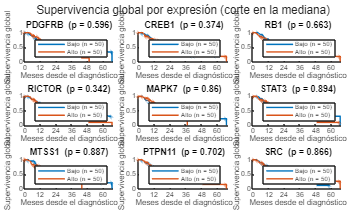

%% 3. Kaplan–Meier + log-rank por gen
resKM = table('Size',[nG 11], ...
    'VariableTypes',["string","double","double","double","double","double","double","double","double","double","double"], ...
    'VariableNames',["gen","n_bajo","n_alto","eventos_bajo","eventos_alto", ...
                     "medianaOS_bajo","medianaOS_alto","HR_alto_vs_bajo","IC_inf","IC_sup","p_logrank"]);

figPanel = figure('Name','KM todos los genes', 'Position',[50 50 1300 1000]);
tlPanel  = tiledlayout(figPanel, 'flow', 'TileSpacing','compact', 'Padding','compact');
xl    = [0, max(t) * 1.02];
ticks = 0:pasoMeses:max(t);

for k = 1:nG
    x     = D.(colsG(k));
    grupo = double(x > median(x));     % 0 = Bajo, 1 = Alto

    [~, pLR] = logrank(t, e, grupo);
    [b, ~, ~, st] = coxphfit(grupo, t, 'Censoring', e == 0);

    resKM.gen(k)            = genes(k);
    resKM.n_bajo(k)         = sum(grupo == 0);
    resKM.n_alto(k)         = sum(grupo == 1);
    resKM.eventos_bajo(k)   = sum(e(grupo == 0));
    resKM.eventos_alto(k)   = sum(e(grupo == 1));
    resKM.medianaOS_bajo(k) = medianaKM(t(grupo == 0), e(grupo == 0) == 0);
    resKM.medianaOS_alto(k) = medianaKM(t(grupo == 1), e(grupo == 1) == 0);
    resKM.HR_alto_vs_bajo(k) = exp(b);
    resKM.IC_inf(k)         = exp(b - 1.96*st.se);
    resKM.IC_sup(k)         = exp(b + 1.96*st.se);
    resKM.p_logrank(k)      = pLR;

    etiquetas = [sprintf("Bajo (n = %d)", resKM.n_bajo(k)), sprintf("Alto (n = %d)", resKM.n_alto(k))];
    titulo    = sprintf("%s   log-rank p = %.3g   HR = %.2f (%.2f–%.2f)", ...
                        genes(k), pLR, resKM.HR_alto_vs_bajo(k), resKM.IC_inf(k), resKM.IC_sup(k));

    % Figura individual con tabla de pacientes en riesgo
    fig = figure('Visible','off', 'Position',[100 100 650 560]);
    tl  = tiledlayout(fig, 5, 1, 'TileSpacing','compact');
    ax1 = nexttile(tl, [4 1]);
    graficarKM(ax1, t, e, grupo, etiquetas, colores, xl, ticks);
    title(ax1, titulo, 'FontSize', 10);
    ax2 = nexttile(tl);
    tablaRiesgo(ax2, t, grupo, ticks, colores, xl);
    drawnow;
    exportgraphics(fig, fullfile(carpetaFig, "KM_" + genes(k) + ".png"), 'Resolution', 300);
    close(fig);

    % Panel con todos los genes
    ax = nexttile(tlPanel);
    graficarKM(ax, t, e, grupo, etiquetas, colores, xl, ticks);
    title(ax, sprintf("%s  (p = %.3g)", genes(k), pLR), 'FontSize', 10);
end
title(tlPanel, "Supervivencia global por expresión (corte en la mediana)");
drawnow;
exportgraphics(figPanel, fullfile(carpetaSal, "KM_panel_genes.png"), 'Resolution', 300);


resKM.q_logrank = fdrBH(resKM.p_logrank);
fprintf("================ KAPLAN–MEIER + LOG-RANK ================\n");

================ KAPLAN–MEIER + LOG-RANK ================


fprintf("(medianas de OS en meses; NaN = la curva no llega a 0.5)\n");

(medianas de OS en meses; NaN = la curva no llega a 0.5)


disp(resKM);

      gen       n_bajo    n_alto    eventos_bajo    eventos_alto    medianaOS_bajo    medianaOS_alto    HR_alto_vs_bajo    IC_inf     IC_sup    p_logrank    q_logrank
    ________    ______    ______    ____________    ____________    ______________    ______________    _______________    _______    ______    _________    _________

    "PDGFRB"      50        50           27              29             17.478            19.811             1.1549        0.67782    1.9678      0.5959      0.89374 
    "CREB1"       50        50           28              28             16.789            

### Sección 4. Regresión de Cox (gen continuo). 

Esta sección hace la regresión de Cox con la expresión de cada gen como variable continua, sin dividir a los pacientes en grupos. Es en análisis principal del script: aprovehca toda la información de la expresión y tiene más poder estadistico que la comparación alto contra bajo de Kaplan-Meier. 

Primero crea dos tablas. "resCox" tiene una fila por gen y 15 columnas para los resultados del modelo univariado, del ajustado, de la prueba de riesgos proporcionales y de la corrección por comparaciones múltiples. "coefAdj" empieza vacía y guardará todos los coeficientes de los modelos ajustados, incluidos los de las covariables. "nomCov" contiene los nombres descriptivos de las tres covariables, que se usan como etiquetas en "coefAdj". 

Después, un ciclo repite el análisis para cada gen. Lo primero es estandarizar la expresión: a cada valor se le resta la media del gen y se divide entre su desviación estándar, y el resultado se guarda en "z". Así, el hazard ratio se interpreta como el cambio en el riesgo de muerte por cada desviación estándar de aumento en la expresión, y los HR de los distintos genes quedan en la misma escala y se pueden comparar entre sí. 

Luego ajusta dos modelos de Cox con la función "coxphfit":

- Modelo univariado: solo incluye el gen. Se guardan el HR (la exponencial del coeficnete), su intervalo de confianza al 95% y su p-value. 

- Modelo ajustado: incluye el gen junto con la edad (por cada 10 años), el estadio binario y la pureza (por cada 0.1). Permite saber si el efecto del gen se mantiene al comparar pacientes con la misma edad, estadio y pureza. Como el modelo no admite datos faltantes, el vector lógico "cc" selecciona solo los casos completos, es decir, los pacientes con las cuatro variables. Por eso los dos pacientes sin estadio quedan fuera. Se guardan cuántos pacientes y eventos entraron al modelo y, de nuevi, el HR del gen con su intervalo y su p-value. El HR del gen es el primer coeficiente, porque el gen es la primera columna del modelo. 

En ambos modelos se evalúa el supuesto de riesgos proporcionales con la función "pruebaPH". El modelo de Cox supone que el efecto de cada variable es constante a lo largo del seguimiento. El modelo de Cox supone que el efecto de cada variable es constante a lo largo del seguimiento. Para verificarlo, la función toma los "residuos de Schoenfeld escalados" de los pacientes que murieron (lo que el modelo no logra explicar en cada muerte) y calcula su correlación con el orden del tiempo en que ocurrieron. Si el efecto fuera constante, los residuos no tendrían ninguna tendencia en el tiempo. Una correlación significatica (p<0.05) sugiere que el efecto cambia, por ejemplo que el gen importa más al incicio que al final. En el modelo ajustado, la prueba se calcula para el gen y para cada covariable, y esos resultados se agregan a "coefAdj" junto con los HR de todas las variables. 

Al terminar el ciclo, los p-values del modelo univariado y del ajustado se corrigen por comparaciones múltiples con el método de Benjamini-Hochberg "fdrBH" y se guardan en "q_uni" y "q_adj". El script imprime la tabla "resCox" completa, aclarando en qué escala están los HR y por qué variables se ajustó. 

Por último, revisa si algún gen tiene p<0.05 en la preuba de riesgos proporcionales, en el modelo univariado o en el ajustado. Si lo hay, muestra una advertencia con su nombre, porque su HR podría no ser constante en el tiempo. También imprime la tabla "coefAdj", que permite ver cuánto pesa cada covariable en cada modelo. 

resCox = table('Size',[nG 15], ...
    'VariableTypes',["string", repmat("double", 1, 14)], ...
    'VariableNames',["gen","HR_uni","IC_inf_uni","IC_sup_uni","p_uni","pPH_uni", ...
                     "n_adj","eventos_adj","HR_adj","IC_inf_adj","IC_sup_adj","p_adj","pPH_adj", ...
                     "q_uni","q_adj"]);
coefAdj = table();   % todos los coeficientes de los modelos ajustados

nomCov = ["edad (por 10 años)","estadio IIB–III vs I–IIA","pureza (por 0.1)"];
for k = 1:nG
    x = D.(colsG(k));
    z = (x - mean(x)) / std(x);        % HR por cada desviación estándar

    % Univariado
    [b, ~, ~, st] = coxphfit(z, t, 'Censoring', e == 0);
    resCox.gen(k)        = genes(k);
    resCox.HR_uni(k)     = exp(b);
    resCox.IC_inf_uni(k) = exp(b - 1.96*st.se);
    resCox.IC_sup_uni(k) = exp(b + 1.96*st.se);
    resCox.p_uni(k)      = st.p;
    resCox.pPH_uni(k)    = pruebaPH(st, t, e, 1);

    % Multivariado (casos completos)
    X  = [z, edad10, D.estadio_avanzado, pureza10];
    cc = all(~isnan(X), 2);
    [b, ~, ~, st] = coxphfit(X(cc,:), t(cc), 'Censoring', e(cc) == 0);
    resCox.n_adj(k)       = sum(cc);
    resCox.eventos_adj(k) = sum(e(cc));
    resCox.HR_adj(k)      = exp(b(1));
    resCox.IC_inf_adj(k)  = exp(b(1) - 1.96*st.se(1));
    resCox.IC_sup_adj(k)  = exp(b(1) + 1.96*st.se(1));
    resCox.p_adj(k)       = st.p(1);
    resCox.pPH_adj(k)     = pruebaPH(st, t(cc), e(cc), 1);

    pPH = arrayfun(@(c) pruebaPH(st, t(cc), e(cc), c), (1:numel(b))');
    coefAdj = [coefAdj; table(repmat(genes(k), numel(b), 1), ...
        [genes(k) + " (por DE)"; nomCov'], exp(b), exp(b - 1.96*st.se), exp(b + 1.96*st.se), st.p, pPH, ...
        'VariableNames', ["modelo","variable","HR","IC_inf","IC_sup","p","p_PH"])]; %#ok<AGROW>
end
resCox.q_uni = fdrBH(resCox.p_uni);
resCox.q_adj = fdrBH(resCox.p_adj);

fprintf("================ REGRESIÓN DE COX ================\n");

================ REGRESIÓN DE COX ================


fprintf("HR por cada desviación estándar de log2(TPM+1)\n");

HR por cada desviación estándar de log2(TPM+1)


fprintf("Ajustado por: edad, estadio (IIB–III vs I–IIA) y pureza ABSOLUTE\n");

Ajustado por: edad, estadio (IIB–III vs I–IIA) y pureza ABSOLUTE


disp(resCox);

      gen       HR_uni    IC_inf_uni    IC_sup_uni     p_uni     pPH_uni     n_adj    eventos_adj    HR_adj     IC_inf_adj    IC_sup_adj     p_adj     pPH_adj      q_uni      q_adj 
    ________    ______    __________    __________    _______    ________    _____    ___________    _______    __________    __________    _______    ________    _______    _______

    "PDGFRB"    1.1836     0.90318        1.5511      0.22174     0.24666     98          56          1.1481     0.85538     


viola = resCox.gen(resCox.pPH_uni < 0.05 | resCox.pPH_adj < 0.05);
if ~isempty(viola)
    warning("Posible violación de riesgos proporcionales (p < 0.05): %s. Su HR podría cambiar con el tiempo.", ...
            strjoin(viola, ", "));
else
    fprintf("Supuesto de riesgos proporcionales: sin violaciones en los genes (p >= 0.05).\n");
end

fprintf("\nCoeficientes de los modelos ajustados:\n");


Coeficientes de los modelos ajustados:


disp(coefAdj);

     modelo              variable               HR       IC_inf     IC_sup        p          p_PH  
    ________    __________________________    _______    _______    _______    ________    ________

    "PDGFRB"    "PDGFRB (por DE)"              1.1481    0.85538      1.541     0.35771     0.22094
    "PDGFRB"    "edad (por 10 años)"            1.197    0.90379     1.5854     0.20968     0.86388
    "PDGFRB"    "estadio IIB–III vs I–IIA"     1.3003    0.66314     2.5498     0.44462     0.46646
    "PDGFRB"    "pureza (por 0.1)"            0.86106    0.74674    0.99289     0.03957     0.32345
    "CREB1"     "CREB1 (por DE)"                1.031    0.77991      1.363     0.83014     0.80316
    "CREB1"     "edad (por 10 años)"           1.1717    0.88

### Sección 5. Forest plot. 

Esta sección construye el forest plot, la figura que resume en una sola imagen los resultados de la regresión de Cox de la sección 4. Cada gen ocupa un renglón y muestra dos estimaciones: el hazard ratio del modelo univariado y el del modelo ajustadom cada uno con su intervalo de confianza al 95%. 

Primero se definen las posiciones y los colores. El vector "y" asigna a cada gen una altura en el eje vertical, en orden descendente, para que el primer gen de la lista quede arriba. "off" es un pequeño desplazamiento vertical que separa los dos marcadores de cada gen: el univariado se dibuja un poco más arriba y el ajustado u poco más abajo, para que no se encimen. Los colores son gris para el modelo univariado y rojo para el ajustado. La altura de la figura se calcula según el número de genes, así que crecer si el panel tiene más genes. 

La figura se divide con "tiledlayout" en una fila de cinco espacios: los tres primeros contienen la gráfica y los dos últimos, una columna de texto con los valores númericos. 

En la gráfica, la función "errobar" dibuja cada HR como un marcador (cuadrado para el univariado y círculo para el ajustado) con una línea horizontal que ca del límite inferior al superior de su intervalo de confianza. Después se agrega una línea punteada vertical en HR = 1, que representa la ausencia de efecto: si el intervalo de un gen cruza esa línea, su efecto no es signifcativo. Los límites del eje horizontal se calculan a partir del intervalo más bajo y el más alto, con un pequeño margen, para que todos queden visibles. 

El eje horizontal está en la escala logarítmica. Así, efectos de la misma magnitud en direcciones opuestas quedan a la misma distancia del 1. Por ejemplo, un HR de 2 (el doble de riesgo) y uno de 0.5 (la mitad) se ven igual de lejos de la línea. En escala lineal, los efectos protectores quedarían comprimidos entre 0 y 1. Se agregan además los nombres de los genes en el eje vertical, líneas de guí horizontales, la leyenda debajo de la gráfica y dos etiquetas en la parte superior que indican que a la izquierda de la línea significa menor riesgo y la derecha mayor riesgo. 

En la columna de texto, se escriben, a la altur de cada marcador y con su mismo color, el HR, su intervalo de confianza y su p-value. La función "compose" arma esos textos con el formato HR (inferior-superior) p = valor. Esta columna usa la misma escala vertical que la gráfica, de modo que cada texto queda alineado con su marcador. Arriba se agrega el encabezado "HR (IC 95%)": 

Por último, la figura recibe un título con el número de pacientes y de eventos de la cohorte y se guarda como "Forest_plot_Cox.png" en la carpeta de resultados. 

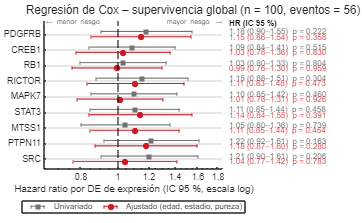

y   = (nG:-1:1)';
off = 0.17;
cUni = [0.45 0.45 0.45];  cAdj = [0.80 0.10 0.15];

fig = figure('Name','Forest plot', 'Position',[100 100 1000 120 + 55*nG]);
tl  = tiledlayout(fig, 1, 5, 'TileSpacing','none', 'Padding','compact');

ax = nexttile(tl, [1 3]); hold(ax, 'on');
h1 = errorbar(ax, resCox.HR_uni, y + off, [], [], resCox.HR_uni - resCox.IC_inf_uni, ...
              resCox.IC_sup_uni - resCox.HR_uni, 's', 'Color', cUni, 'MarkerFaceColor', cUni, ...
              'MarkerSize', 6, 'CapSize', 4, 'LineWidth', 1.2);
h2 = errorbar(ax, resCox.HR_adj, y - off, [], [], resCox.HR_adj - resCox.IC_inf_adj, ...
              resCox.IC_sup_adj - resCox.HR_adj, 'o', 'Color', cAdj, 'MarkerFaceColor', cAdj, ...
              'MarkerSize', 6, 'CapSize', 4, 'LineWidth', 1.2);
xline(ax, 1, 'k--');
lims = [min([resCox.IC_inf_uni; resCox.IC_inf_adj]) * 0.85, max([resCox.IC_sup_uni; resCox.IC_sup_adj]) * 1.15];
set(ax, 'XScale','log', 'YTick', 1:nG, 'YTickLabel', genes(nG:-1:1), 'YLim', [0.4 nG + 0.9], ...
        'XLim', lims, 'FontSize', 10, 'Box', 'off');
ax.YGrid = 'on';
xlabel(ax, 'Hazard ratio por DE de expresión (IC 95 %, escala log)');
legend(ax, [h1 h2], ["Univariado", "Ajustado (edad, estadio, pureza)"], 'Location', 'southoutside', ...
       'Orientation', 'horizontal');
text(ax, lims(1), nG + 0.7, '\leftarrow menor riesgo', 'FontSize', 8, 'Color', [0.3 0.3 0.3]);
text(ax, lims(2), nG + 0.7, 'mayor riesgo \rightarrow', 'FontSize', 8, 'Color', [0.3 0.3 0.3], ...
     'HorizontalAlignment', 'right');

axT = nexttile(tl, [1 2]); axis(axT, 'off');
set(axT, 'YLim', ax.YLim, 'XLim', [0 1]);
txtUni = compose("%.2f (%.2f–%.2f)  p = %.3f", resCox.HR_uni, resCox.IC_inf_uni, resCox.IC_sup_uni, resCox.p_uni);
txtAdj = compose("%.2f (%.2f–%.2f)  p = %.3f", resCox.HR_adj, resCox.IC_inf_adj, resCox.IC_sup_adj, resCox.p_adj);
text(axT, 0.05, nG + 0.7, 'HR (IC 95 %)', 'FontWeight', 'bold', 'FontSize', 9);
for k = 1:nG
    text(axT, 0.05, y(k) + off, txtUni(k), 'Color', cUni, 'FontSize', 9);
    text(axT, 0.05, y(k) - off, txtAdj(k), 'Color', cAdj, 'FontSize', 9);
end
title(tl, sprintf("Regresión de Cox – supervivencia global (n = %d, eventos = %d)", height(D), sum(e)));
exportgraphics(fig, fullfile(carpetaSal, "Forest_plot_Cox.png"), 'Resolution', 300);

### Sección 6. Guardar resultados. 

Esta penúltima sección guarda los resultados númericos del análisis de supervivencia en la carpeta de resultados (Resultados_Supervivencia), la misma de donde el script leyó la cohorte. Las figuras no se guardan aquí: Cada una se guardó en el momento en que se generó, en las secciones 3 y 5. 

Se generan tres archivos .csv, que pueden abrirse en Excel, R o Python: 

- Resultados_KM_logrank.csv: Contiene la tabla "resKM" de la sección 3 con una fila por gen. Incluye el número de pacientes y de eventos en los grupos de expresión baja y alta, la mediana de supervivencia de cada grupo, el hazard ratio del grupo alto frente al bajo con su intervalo de confianza, el p-value de la prueba log-rank y su valor corregido por comparaciones múltiples "q_logrank". 

- Resultados_Cox.csv: Contiene la tabla "resCox" de la sección 4, también en una fila por gen. Incluye el hazard ratio por desviación estándar de expresión con su intervalo, su p-value y su valor corregido, tanto del modelo univariado como del ajustado. Son los resultado principales del análisis y lo que se muestran en el forest plot. 

- Resultados_Cox_coeficientes_ajustados.csv: Contiene la tabla "coefAdj", con todos los coeficientes de los modelos ajustados: cuatro filas por gen, una para el gen y una para cada covaribale (edad, estadio, y pureza). Para cada variable incluye su hazard ratio, su intervalo de confianza, su p-value y su prueba de riesgos proporcionales. Sirve para ver cuánto influye cada covariable en el pronóstico y si alguna viola el supuesto de riesgos proporcionales. 

Además, se guarda el archivo "Resultados_Supervivencia.mat" con las tres tablas y la lista de genes en formato nativo de MATLAB. Se puede recargar con "load" para revisar o graficar los resultados sin volver a correr el análisis. 

Por último, el script imprime un mensaje que confirma que terminó e indica la carpeta donde quedaron los resultados y las figuras. 

writetable(resKM,   fullfile(carpetaSal, "Resultados_KM_logrank.csv"));
writetable(resCox,  fullfile(carpetaSal, "Resultados_Cox.csv"));

Error using writetable (line 283)
Unable to open file 'C:\PAP Keyla Otoño 2026\Downloaded_Data_Cohort_Pancreas\Resultados_Supervivencia\Resultados_Cox.csv' for writing:

Permission denied

writetable(coefAdj, fullfile(carpetaSal, "Resultados_Cox_coeficientes_ajustados.csv"));
save(fullfile(carpetaSal, "Resultados_supervivencia.mat"), "resKM", "resCox", "coefAdj", "genes");
fprintf("\nListo. Resultados y figuras en: %s\n", carpetaSal);

### Sección 7. Funciones del código. 

En esta última sección del código se encuentran las funciones auxiliares llamadas en las secciones anteriores. 

"logrank" calcula la prueba log-rank que compara la supervivencia de dos grupos. La función recorre, uno por uno, los momentos en que murió algún paciente. En cada momento cuenta cuántos pacientes seguían en riesgo en total y en el grupo de expresión alta, y cuántas muertes ocurrieron en total y en ese grupo. Con esos conteos calcula cuántas muertes se esperarían en el grupo alto si el riesgo fuera igual en ambos grupos, y las compara con las que realmente se observaron. También acumula la varianza de esa diferencia. Al final, la diferencia entre observadas y esperadas, elevada al cuadrado y dividida entre la varianza, da un estadístico chi-cuadrado con un grado de libertad del que se obtiene el p-value. 

"pruebaPH" evalúa el supuesto de riesgos proporcionales del modelo de Cox. Toma los residuos de Schoenfeld escalados que calcula "coxphfit" solo para los pacientes que murieron, y calcula su correlación con el orden de los tiempos de muerte (la función "tiedrank" convierte a los tiempos en rangs). Si el efecto de la variable es constante en el tiempo. Si la versión de MATLAB no devuelve estos residuos, la función regresa "NaN" en lugar de fallar. 

"fdrBH" aplica la corrección de Benjamini-HochBerg por comparaciones múltiples. Orden los p-values de menor a mayor y multiplica cada uno por el número total de pruebas entre su posición en el orden. Después se asegura de que los valores corregiso no disminuyan al subir en la lista y de que ninguno supere 1. Por último, los devuelve en el orden original de los genes, El resultado son los valores "q", que controlan la proporción esperada de falsos positivos entre los resultados significativos. 

"medianaKM" calcula la median de supervivencia de una criva de Kaplan-Meier, Obtiene la curva con "ecdf" y busca el primer tiempo en que la supervivencia cae al 50% o menso. Si la curva nunca llega al 50% durante el seguimiento, devuelve "NaN", que se reporta como mediana "no alcanzada". 

"graficarKM" dibuja las curvas de Kaplan-Meier de los grupos de expresión baja y alta. Para cada grupo calcula la curva con "ecdf", le agrega el punto inicial (tiempo 0, supervivencia del 100%) y la dibuja en forma de escalones con "stairs" en azul o naranja. Después marca con una cruz a cada paciente censurado, a la altura de la curva en su tiempo de último seguimiento. Por último, fija los límites y las marcas de los ejes, los títulos de los ejes y la leyenda con el número de pacientes de cada grupo. 

"tablaRiesgo" dibuja la tabla de pacientes en riesgo debajo de cada curva. Oculta los ejes y, en cada marca de tiempo, escribe cuántos pacientes de cada grupo seguían en observación, es decir, cuántos tenían un tiempo de seguimiento igual o mayor. Cada fila usa el color de su grupo. Esta tabla ayuda a saber que tan confiable es cada tramo de la curva: cuando quedan pocos pacientes en riesgo, la curva es menos precisa. 

function [chi2, p] = logrank(t, e, g)
% Prueba log-rank de dos grupos (g = 0/1)
    g  = logical(g);
    tt = unique(t(e == 1));
    O1 = 0; E1 = 0; V = 0;
    for k = 1:numel(tt)
        enRiesgo = t >= tt(k);
        n  = sum(enRiesgo);
        n1 = sum(enRiesgo & g);
        d  = sum(t == tt(k) & e == 1);
        d1 = sum(t == tt(k) & e == 1 & g);
        O1 = O1 + d1;
        E1 = E1 + d * n1 / n;
        if n > 1
            V = V + d * (n1/n) * (1 - n1/n) * (n - d) / (n - 1);
        end
    end
    chi2 = (O1 - E1)^2 / V;
    p    = 1 - chi2cdf(chi2, 1);
end

function p = pruebaPH(st, t, e, col)
% Riesgos proporcionales: correlación entre los residuos de Schoenfeld escalados
% y el rango del tiempo en los eventos (análogo a cox.zph con transformación de rango).
% p < 0.05 sugiere que el efecto de la variable cambia con el tiempo.
    if ~isfield(st, 'sschres'), p = NaN; return; end
    r  = st.sschres(e == 1, col);
    tt = t(e == 1);
    ok = ~isnan(r);
    [~, p] = corr(tiedrank(tt(ok)), r(ok));
end

function q = fdrBH(p)
% Corrección de Benjamini–Hochberg
    p = p(:); n = numel(p);
    [ps, i] = sort(p);
    qs = ps .* n ./ (1:n)';
    qs = min(1, flipud(cummin(flipud(qs))));
    q = NaN(n, 1); q(i) = qs;
end

function m = medianaKM(t, censurado)
% Mediana de una curva Kaplan–Meier (NaN si no cae por debajo de 0.5)
    [f, x] = ecdf(t, 'Censoring', censurado, 'Function', 'survivor');
    i = find(f <= 0.5, 1);
    if isempty(i), m = NaN; else, m = x(i); end
end

function graficarKM(ax, t, e, grupo, etiquetas, colores, xl, ticks)
% Curvas Kaplan–Meier de dos grupos con marcas de censura
    hold(ax, 'on');
    h = gobjects(2, 1);
    for gI = 1:2
        idx = grupo == (gI - 1);
        [f, x] = ecdf(t(idx), 'Censoring', e(idx) == 0, 'Function', 'survivor');
        x = [0; x]; f = [1; f];
        % ecdf termina en la última muerte; se prolonga la curva (plana)
        % hasta el último paciente censurado del grupo
        tMax = max(t(idx));
        if tMax > x(end), x = [x; tMax]; f = [f; f(end)]; end
        h(gI) = stairs(ax, x, f, 'Color', colores(gI,:), 'LineWidth', 1.6);
        [xu, iu] = unique(x, 'last');
        tc = t(idx & e == 0);
        plot(ax, tc, interp1(xu, f(iu), tc, 'previous', 'extrap'), '+', ...
             'Color', colores(gI,:), 'MarkerSize', 5);
    end
    set(ax, 'XLim', xl, 'YLim', [0 1.02], 'XTick', ticks, 'Box', 'off');
    xlabel(ax, 'Meses desde el diagnóstico'); ylabel(ax, 'Supervivencia global');
    legend(ax, h, etiquetas, 'Location', 'northeast');
    hold(ax, 'off');
end
function tablaRiesgo(ax, t, grupo, ticks, colores, xl)
% Número de pacientes en riesgo debajo de la curva
    axis(ax, 'off'); set(ax, 'XLim', xl, 'YLim', [0 3]);
    text(ax, xl(1), 2.8, 'En riesgo', 'FontWeight', 'bold', 'FontSize', 8);
    for gI = 1:2
        idx = grupo == (gI - 1);
        yy  = 2.6 - gI * 0.9;
        for tk = ticks
            text(ax, tk, yy, num2str(sum(t(idx) >= tk)), 'Color', colores(gI,:), ...
                 'HorizontalAlignment', 'center', 'FontSize', 8);
        end
    end
end

### Referencias y archivo de interpretación de los datos. 

Clark, T. G., Bradburn, M. J., Love, S. B., & Altman, D. G. (2003). Survival analysis Part I: Basic concepts and first analyses. British Journal of Cancer, 89(2), 232–238. https://doi.org/10.1038/sj.bjc.6601118 (Corresponde al archivo `Análisis de supervivencia Pt1.pdf`)

Bradburn, M. J., Clark, T. G., Love, S. B., & Altman, D. G. (2003). Survival analysis Part II: Multivariate data analysis – an introduction to concepts and methods. British Journal of Cancer, 89(3), 431–436. https://doi.org/10.1038/sj.bjc.6601119 (Corresponde al archivo `6601119.pdf`)

Bradburn, M. J., Clark, T. G., Love, S. B., & Altman, D. G. (2003). Survival analysis Part III: Multivariate data analysis – choosing a model and assessing its adequacy and fit. British Journal of Cancer, 89(4), 605–611. https://doi.org/10.1038/sj.bjc.6601120 (Corresponde al archivo `6601120.pdf`)

Clark, T. G., Bradburn, M. J., Love, S. B., & Altman, D. G. (2003). Survival analysis Part IV: Further concepts and methods in survival analysis. British Journal of Cancer, 89(5), 781–786. https://doi.org/10.1038/sj.bjc.6601117 (Corresponde al archivo `6601117.pdf`)

Biostatsquid. (s. f.). COX REGRESSION and HAZARD RATIOS - easily explained with an example! [Video]. YouTube.

Biostatsquid. (s. f.). How to interpret KAPLAN-MEIER curves - Easily explained! [Video]. YouTube.

Biostatsquid. (s. f.). LOG RANK TEST for survival analysis - easily explained with an example! [Video]. YouTube.

Interpretación: https://drive.google.com/file/d/19Xc1ZCfvg4HbFaFqa_vvdr3j7O9sFUs4/view?usp=sharing